## Parcial 2 - Camilo Oberndorfer Mejia

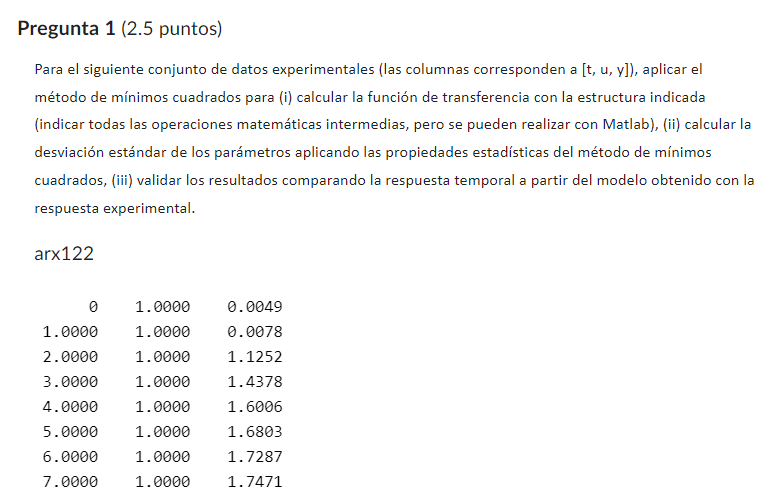


$$$$
ARX 121 \quad \Phi=\left[\begin{array}{l}
\phi^T(1) \\
\phi^T(2) \\
\phi^T(3) \\
\phi^T(4) \\
\phi^T(5) \\
\phi^T(6) \\
\phi^T(7)
\end{array}\right]=\left[\begin{array}{ccc}
y(0) & u(-1) & u(-2)\\
y(1) & u(0) & u(-1) \\
y(2) & u(1) & u(0) \\
y(3) & u(2) & u(1) \\
y(4) & u(3) & u(2) \\
y(5) & u(4) & u(3) \\
y(6) & u(5) & u(4) \\
\end{array}\right]
$$
$$


%arx 122
clf
Datos = [-2 0 0;
         -1 0 0;
         0 1 0.0049;
         1 1 0.0078;
         2 1 1.1252;
         3 1 1.4378;
         4 1 1.6006;
         5 1 1.6803;
         6 1 1.7287;
         7 1 1.7471];
[phi, Y, param, cova] = OLS(Datos, 1, 2, 2);
%Notar que phi no esta bien definida, por lo que phi'*phi no tiene inversa 
phi, inv(phi'*phi)

phi =    -0.0049         0         0
   -0.0078    1.0000         0
   -1.1252    1.0000    1.0000
   -1.4378    1.0000    1.0000
   -1.6006    1.0000    1.0000
   -1.6803    1.0000    1.0000
   -1.7287    1.0000    1.0000


ans =     4.1973    0.0327    6.3242
    0.0327    1.0003   -0.9507
    6.3242   -0.9507   10.7288


G = tf([param(2:end)'],[1 param(1)'],'ts',1, 'InputDelay', 2)

G =
 
           1.121 z - 0.2635
  z^(-2) * ----------------
              z - 0.5158
 
Sample time: 1 seconds
Discrete-time transfer function.



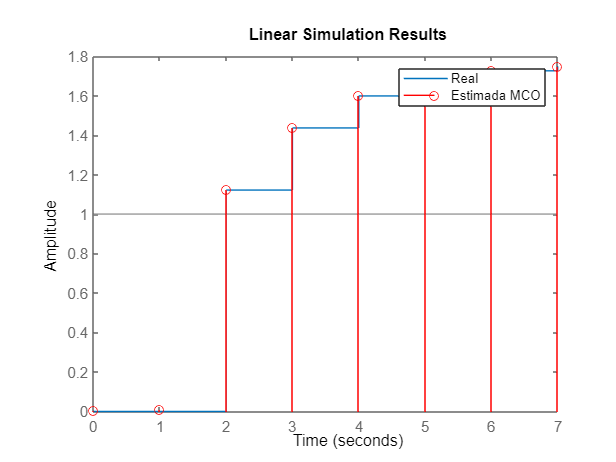

lsim(G,ones(8,1),linspace(0,7,8))
hold on
stem(Datos(2:end,1),Datos(2:end,3),"Color",'r')

legend({"Real","Estimada MCO"})

stdParam = sqrt(diag(cova)) %Desviacio estandar de los parametros

stdParam =     0.0072
    0.0035
    0.0115


data = iddata(Y,phi(:,end),1);
orden_excit = pexcit(data)%orden de excitacion del modelo

orden_excit = 2

### 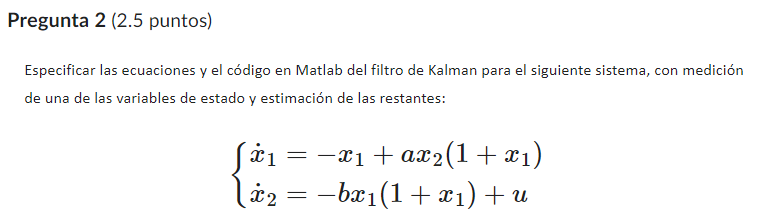

clear all, clf, clc
syms x1 x2 u a b
a = 1; b = 2; %Constantes definidas por el usuario

ode1 = -x1 +a*x2*(1+x1);
ode2 = -b*x1*(1+x1)+u;
y = x2;

odes = [ode1; ode2]; vars = [x1, x2];

[A, B, C, D] = linealizacion(odes,y,vars,u)

$$A = \left(\begin{array}{cc} x_{2}-1 & x_{1}+1\\ -4\,x_{1}-2 & 0 \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

$$C = \left(\begin{array}{cc} 0 & 1 \end{array}\right)$$

D = 0

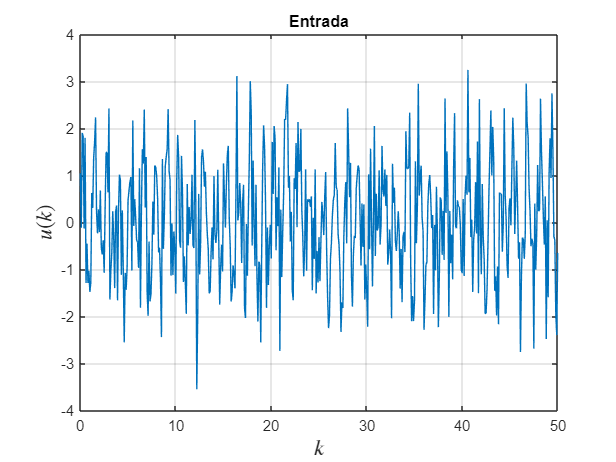

Ts = 0.1; % tiempo de muestreo T.
tiempo = 0:Ts:50; % periodo de tiempo a usar.
u = sin(5*tiempo) + randn(1,length(tiempo)); %ones(1, length(tiempo));

plot(tiempo, u)
title('Entrada');
xlabel('$k$', 'Interpreter', 'Latex', 'FontSize', 15);
ylabel('$u(k)$', 'Interpreter', 'Latex', 'FontSize', 15);
grid on

% Condiciones iniciales dados por el usuario:
M = 0.001*eye(2); R=10; P0 = M; x0 = [1 1]'; Ts = 0.1;
odes = matlabFunction(odes);
%Obtenemos los valores de y reales en cada tiempo t
[t, x] = ode45(@(t,x) ode(t, x, u, tiempo, odes), tiempo, x0); 
y = x(:,2);

V = 0.1*randn(length(y),2);
y1 = y + V;
[P_trace, K_norm, x_est] = KalmanExtended(A,C,odes,t,x,u,y1,x0,M,R,P0,Ts,V);

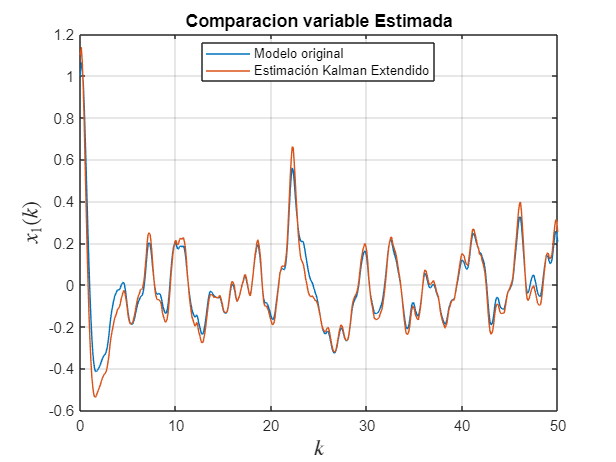

clf
plot(t, x(:,1), t, x_est(:,1))
legend({'Modelo original', 'Estimación Kalman Extendido'}, 'Location', 'best');
xlabel('$k$', 'Interpreter', 'Latex', 'FontSize', 15);
ylabel('$x_{1}(k)$', 'Interpreter', 'Latex', 'FontSize', 15);
title('Comparacion variable Estimada', 'FontSize', 12);
grid on

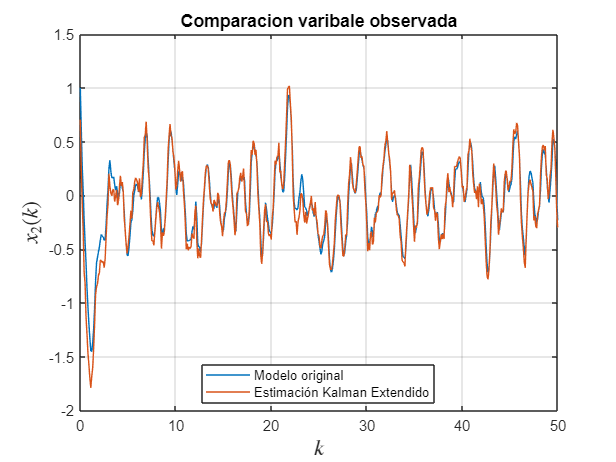

clf
plot(t, x(:,2), t, x_est(:,2))
legend({'Modelo original', 'Estimación Kalman Extendido'}, 'Location', 'best');
xlabel('$k$', 'Interpreter', 'Latex', 'FontSize', 15);
ylabel('$x_{2}(k)$', 'Interpreter', 'Latex', 'FontSize', 15);
title('Comparacion variable observada', 'FontSize', 12);
grid on

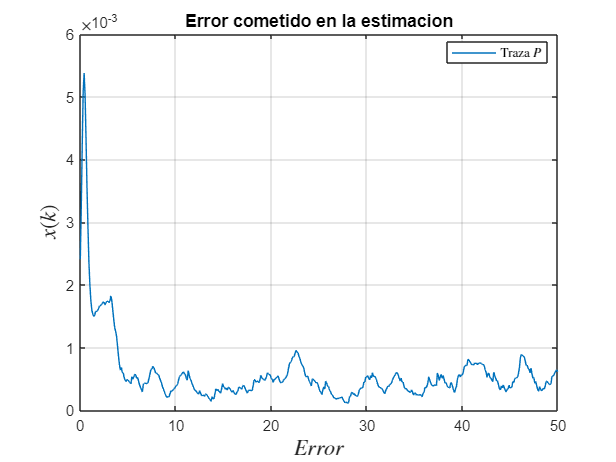

plot(t, P_trace)
legend({'Traza $P$'}, 'Interpreter', 'Latex', 'Location', 'best');
xlabel('$Error$', 'Interpreter', 'Latex', 'FontSize', 15);
ylabel('$x(k)$', 'Interpreter', 'Latex', 'FontSize', 15);
title('Error cometido en la estimacion', 'FontSize', 12);
grid on